s = tf('s');
F = 13.5 * (s+4) * (s+10) / ((s+3)^3);
Kr = 1;
Kf = dcgain(F)

Kf = 20

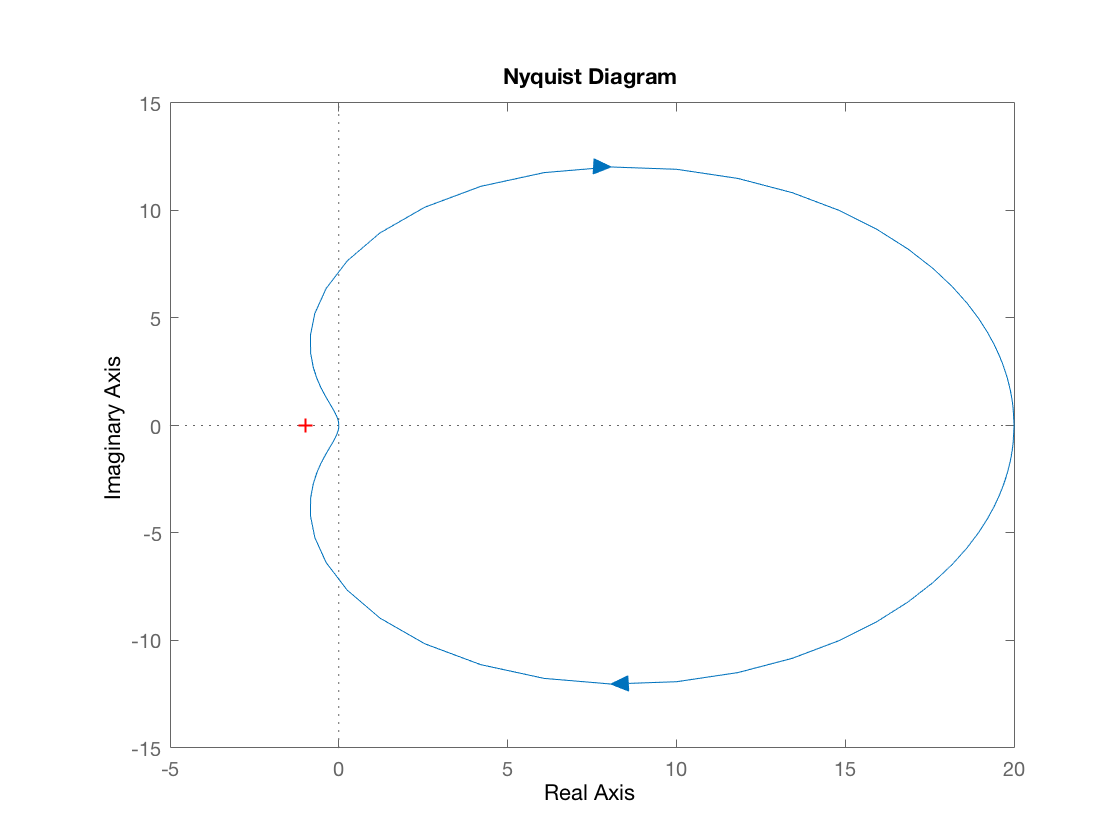

h = 1;
nyquist(F)

Kc > 0

Er_inf = 0.01;
Kc = abs(1/(Er_inf * Kf/Kr))

Kc = 5

w_b = 6;
w_c_des = 0.63 * w_b

w_c_des = 3.7800

Mr = 2;
m_fi_min = 60 - 5 * Mr

m_fi_min = 50

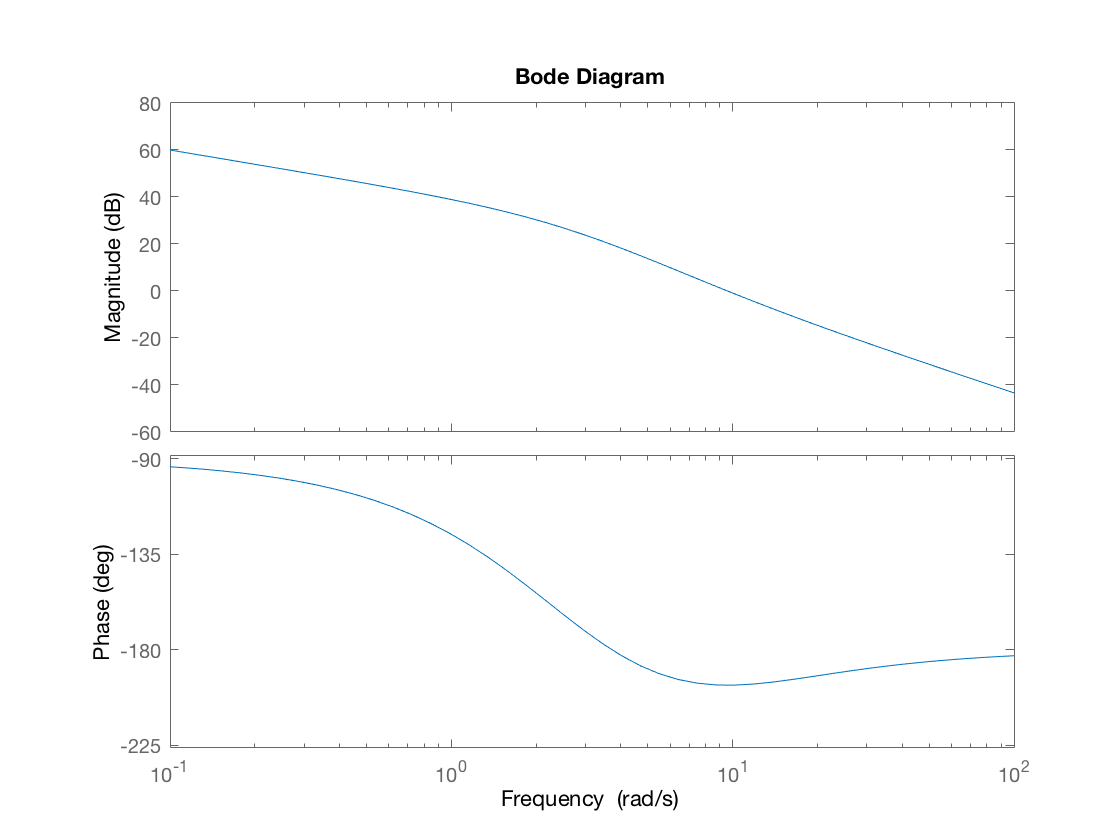

Ga1 = Kc/s * F * (1/Kr);
bode(Ga1)

mod_378 = 19.4;
fase_378 = -180.3;

delta_fi = abs(fase_378 + 180) + m_fi_min

delta_fi = 50.3000

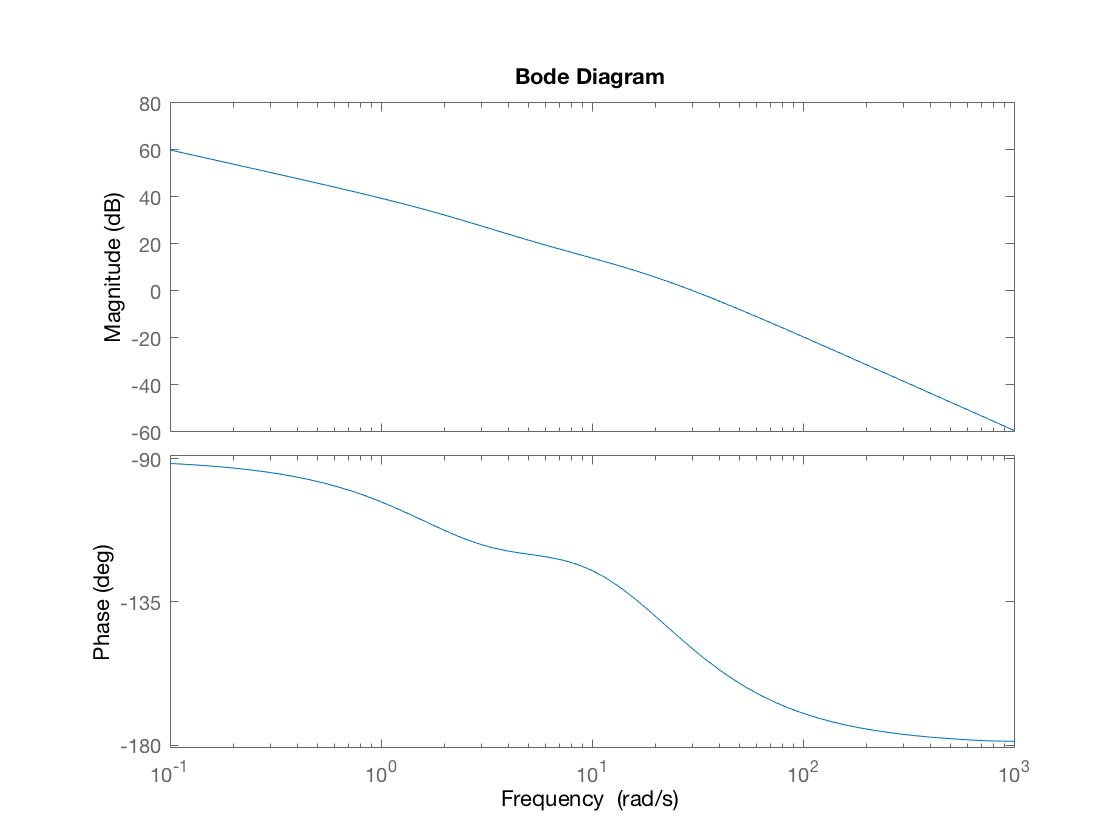

m_d = 4;
t_d = 1 / w_c_des;
Rd = (1 + t_d * s) / (1 + t_d/m_d * s);
Cs = Rd * Rd * Kc / s^h;
Ga2 = Cs * F * 1/Kr;
bode(Ga2)

mod_378 = 31.4

mod_378 = 31.4000

Rete integrativa

t_i = 1;
m_i = 10^(mod_378/20)

m_i = 37.1535

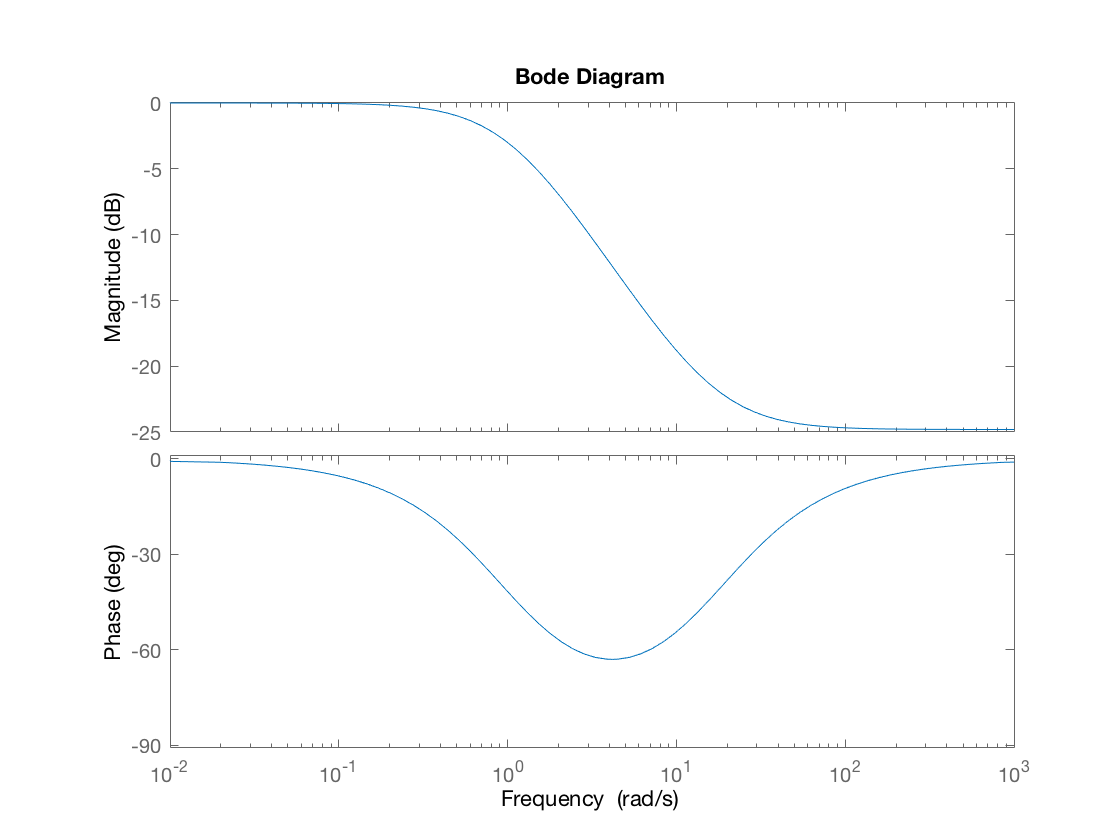

m_i = 17.4;
Ri = (1 + t_i/m_i * s) / (1 + t_i * s);
bode(Ri)

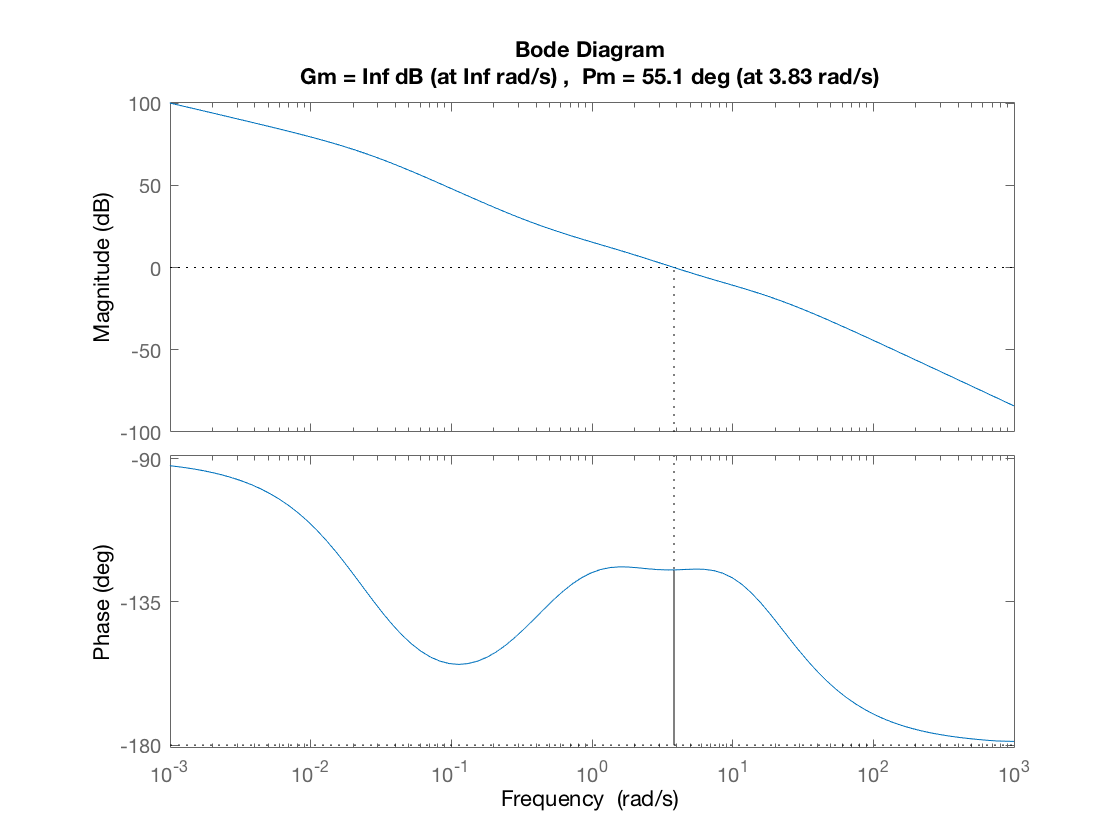

x_i = 150;
t_i = x_i / w_c_des;
Ri = (1 + t_i/m_i * s) / (1 + t_i * s);
Ga = Ga2 * Ri;
margin(Ga)

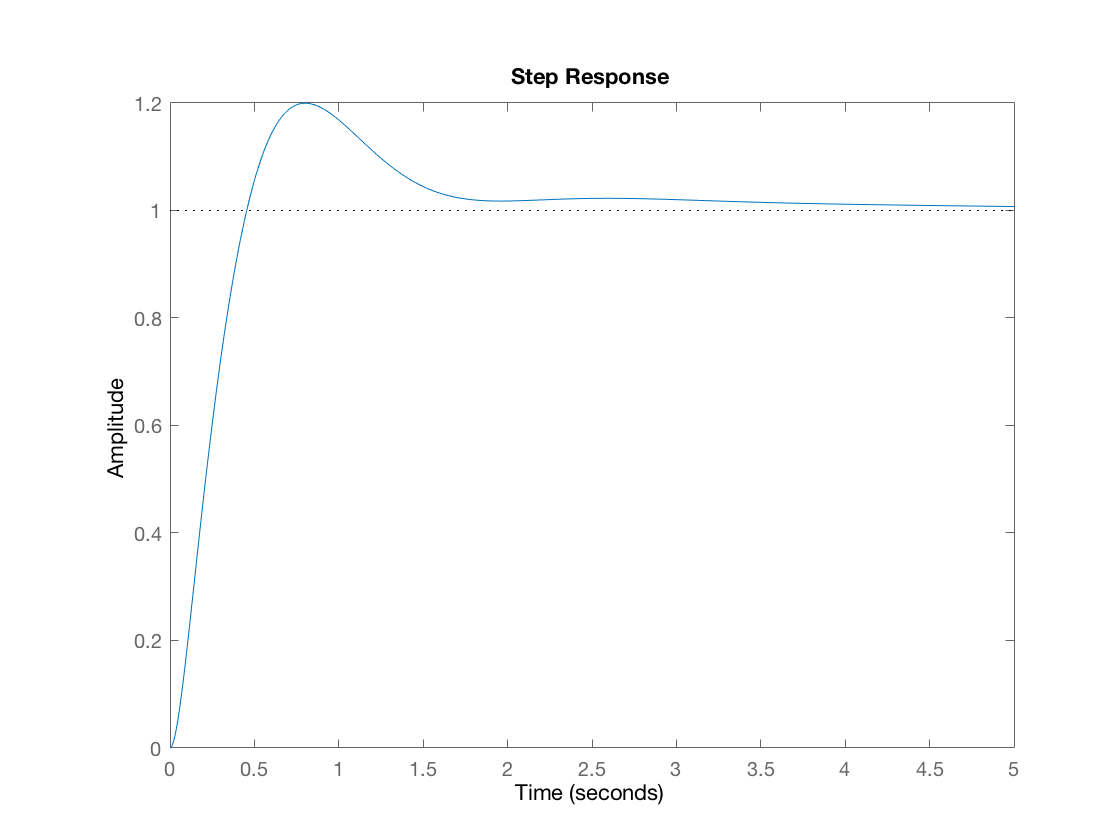

W = feedback(Ga, 1);
step(W)

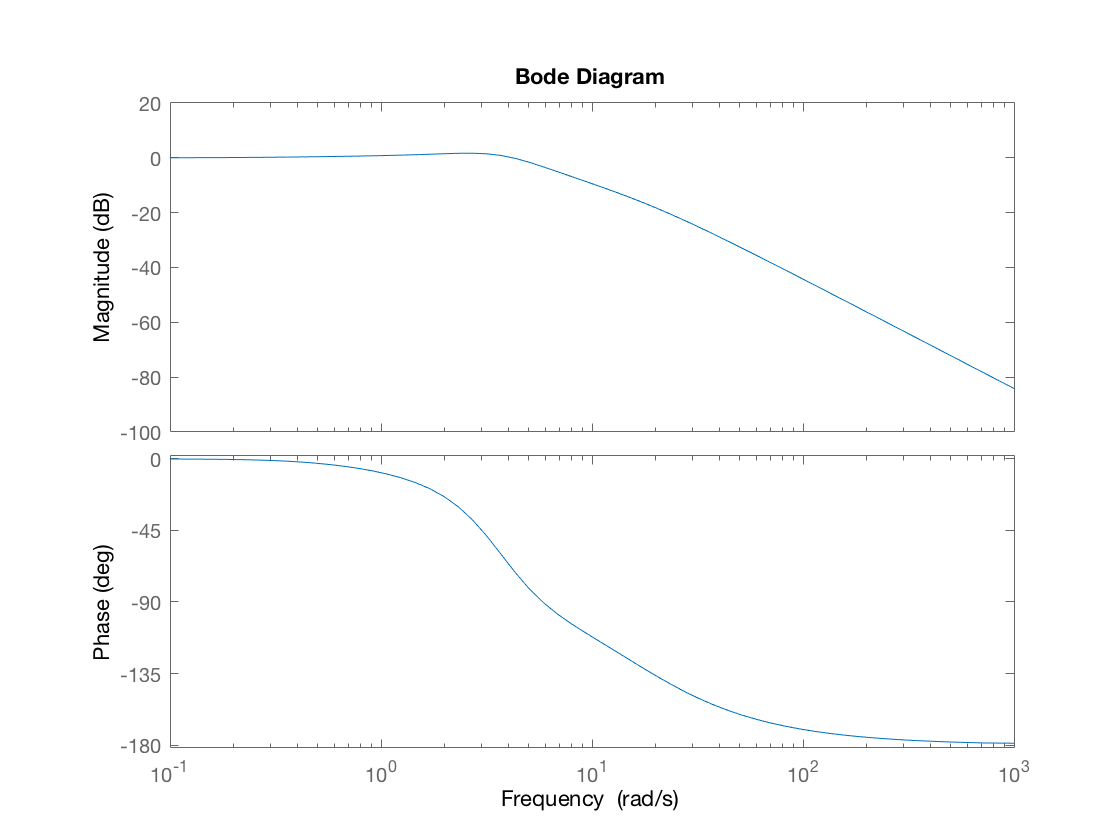

bode(W)

Verifica dell'inseguimento di una rampa

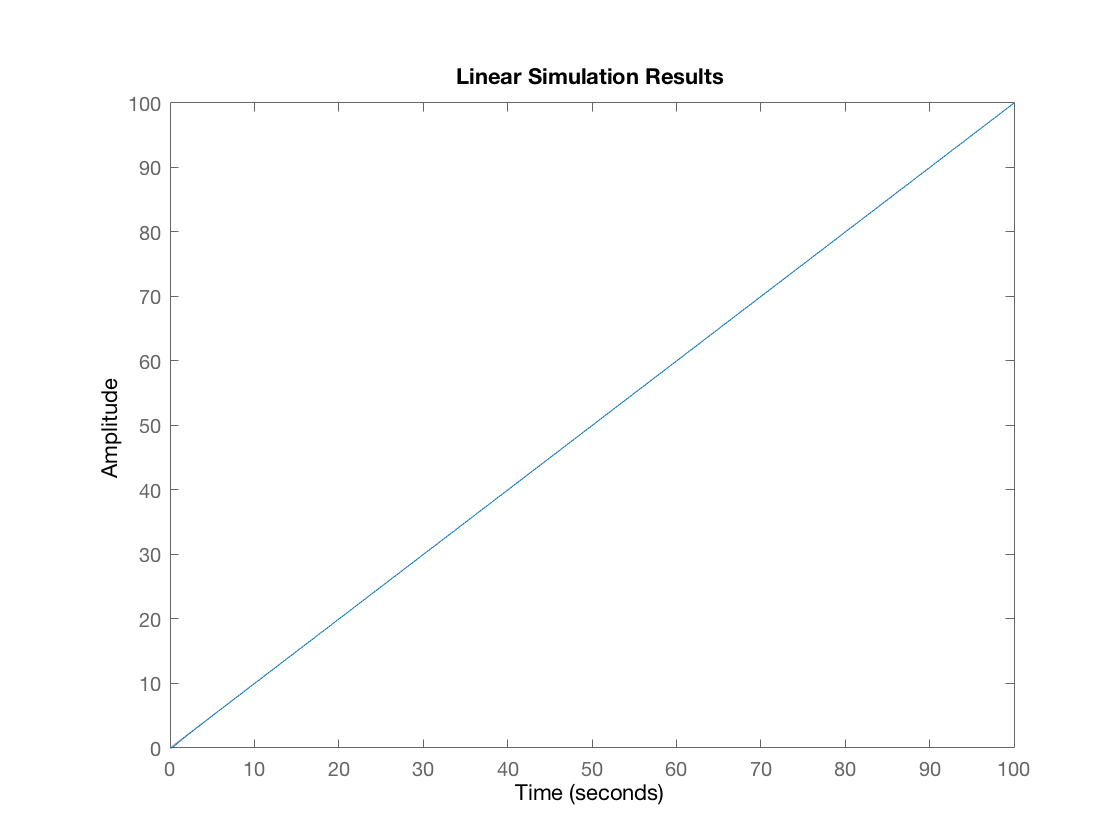

t = 0:0.1:100;
r = t';
lsim(W, r, t)

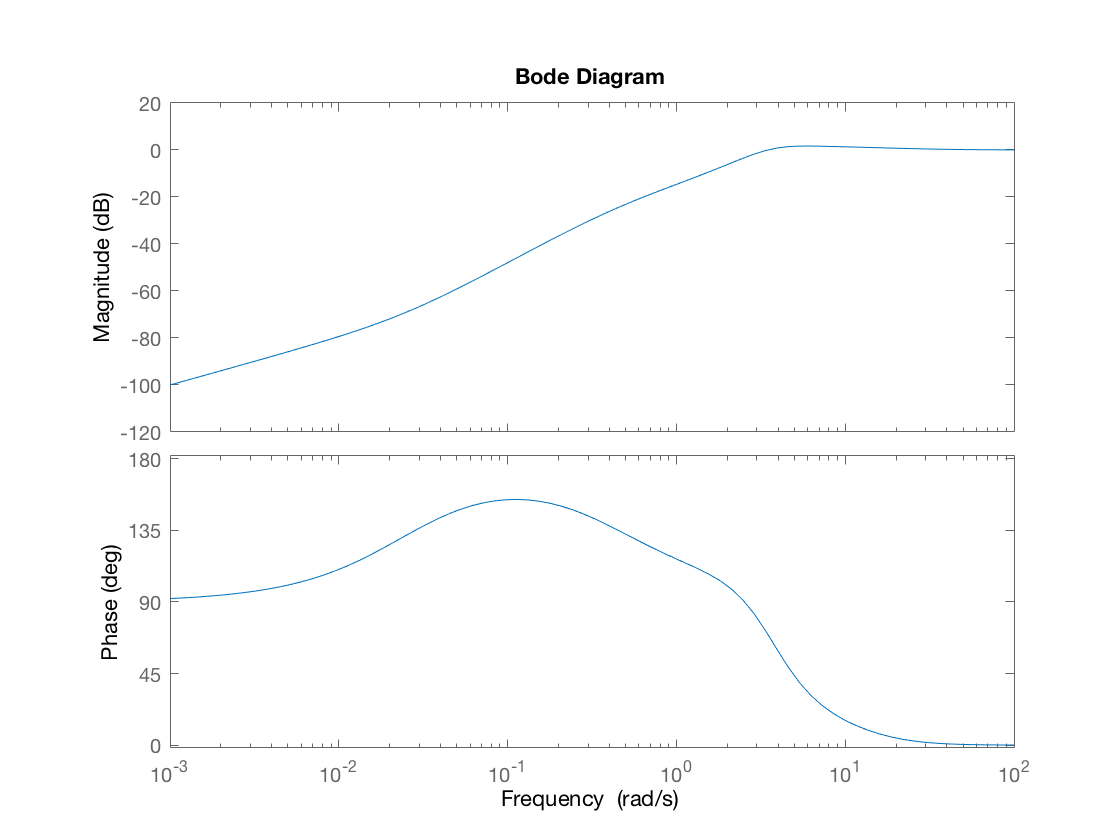

S = feedback(1, Ga);
bode(S)

Errore massimo su riferimento sin(0.1t) = -47dB

Errore massimo su riferimento sin(100t) = 0.05dB